# DEDP Lab 02 - Locating objects with normalized cross-correlation

## 2. Objective

Understand the correlation operation and how it is useful for locating a specific template inside a larger signal.

## 2. Theoretical aspects     

### 2.1. Temporal mean and variance 

Given a vector `v` in Matlab, we can compute the mean and the variance of the vector with `mean()` and `var()`. 

% Two sample vectors
v1 = [1, 2, 1, 1, 5, 6, 5, 6, 6, 6, 7, 10, 14, -3];
v2 = randn(1, 400);
% Calculate mean and variance of first vector
m1   = mean(v1)

m1 = 4.7857

var1 = var(v1)

var1 = 18.0275

% Calculate mean and variance of second vector
m2   = mean(v2)

m2 = -0.0186

var2 = var(v2)

var2 = 0.9205

**Note:** these are the **temporal**  measures, not the statistical measures (we operate on a set of values, not the actual distribution function).

### 2.2 Correlation and autocorrelation

Given two vectors $x$ and $y$, the correlation of the two vectors is the signal $r_{xy}$ defined as defined as (see lectures): 


$$r_{xy}[k] = \sum_{n=-\infty}^{\infty} x[n] y[n-k]$$


The value for a point $k$ should be understood as the sum-product between $x$ and $y$ delayed by $k$ moments of time.

The autocorrelation of $x$ (see lectures) is the signal $r_{xx}$ defined as the correlation of $x$ with itself:


$$r_{xx}[k] = \sum_{n=-\infty}^{\infty} x[n] x[n-k]$$


In Matlab, we can compute them with `xcorr():`

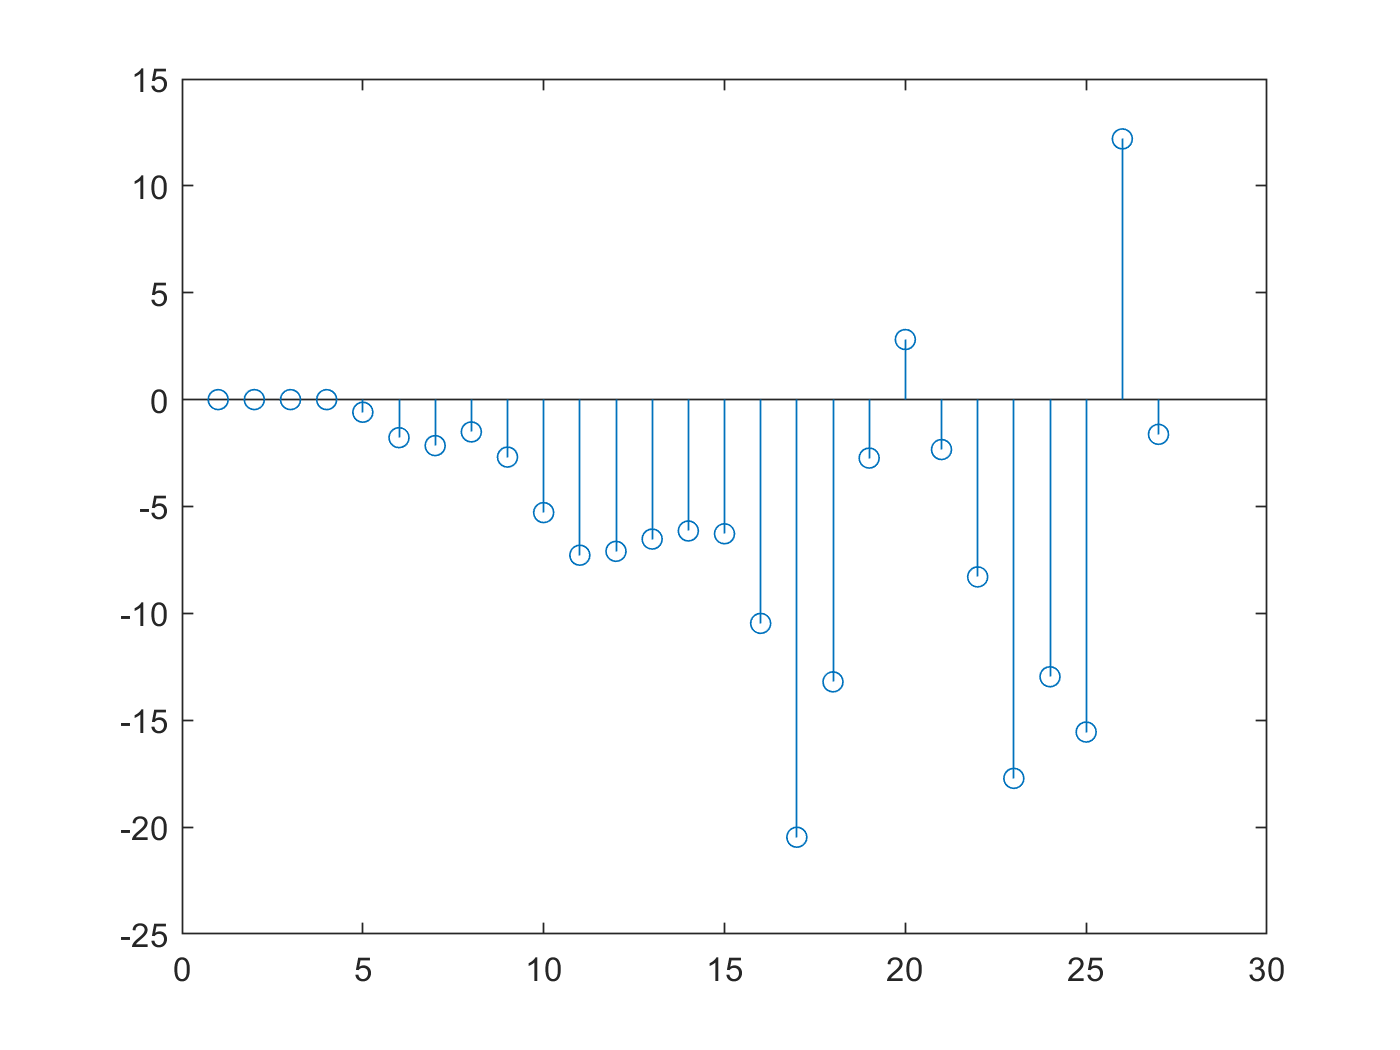

% Two sample vectors
v1 = [1, 2, 1, 1, 5, 6, 5, 6, 6, 6, 7, 10, 14, -3];
v2 = randn(1, 10);
% Calculate correlation between v1 and v2:
rxy = xcorr(v1, v2);
stem(rxy);

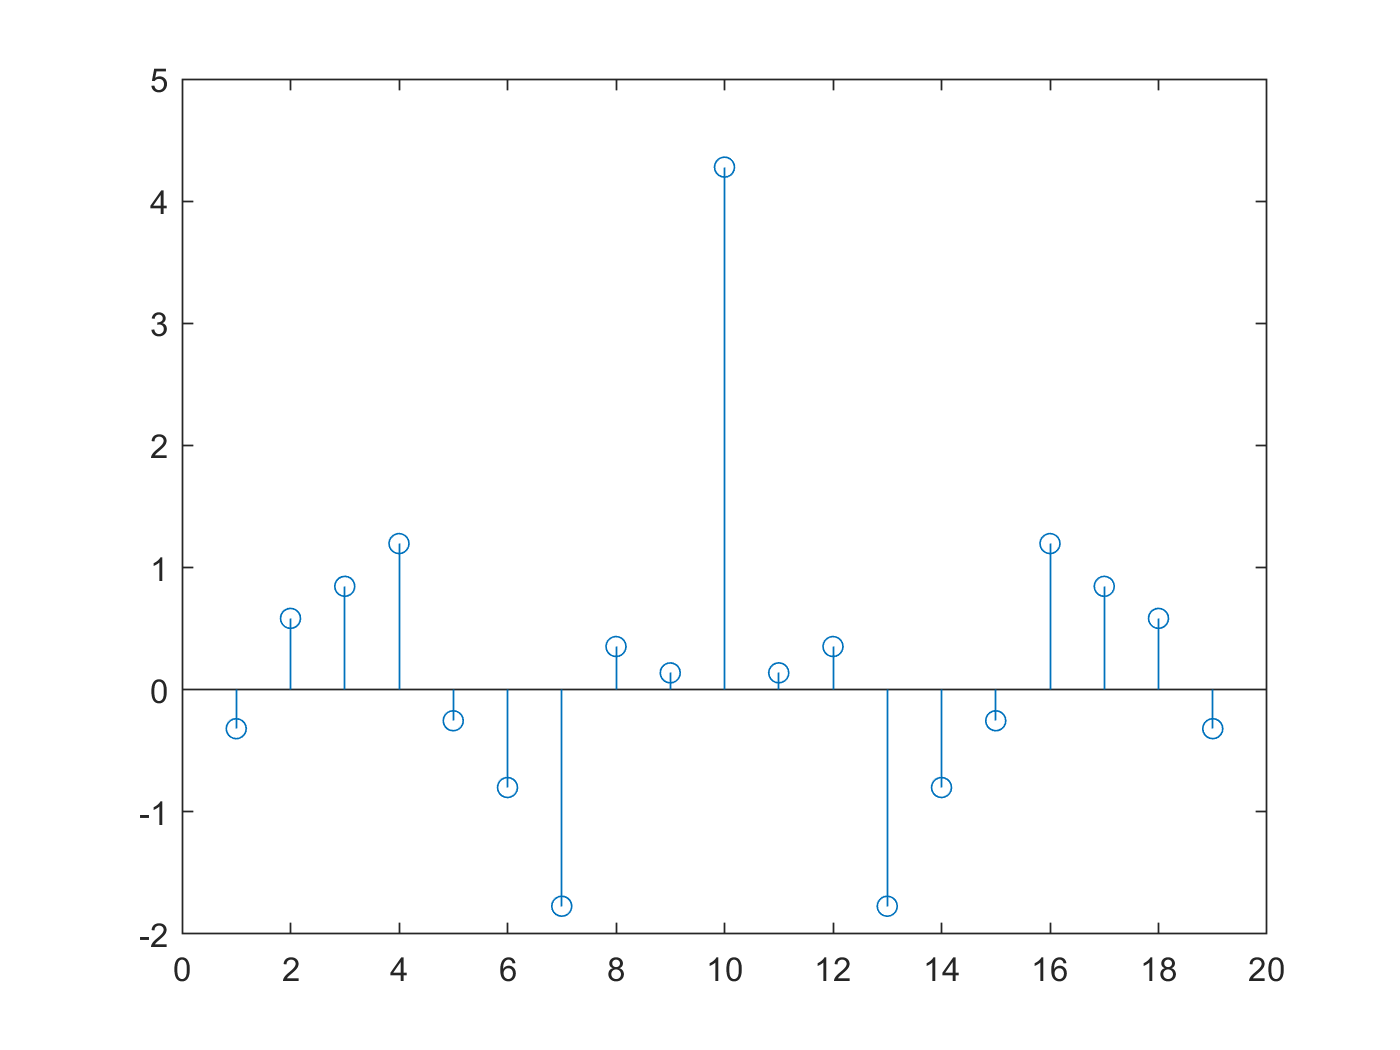

% Calculate autocorrelation of v2:
rxxv2 = xcorr(v2);
stem(rxxv2)

### 2.3 Cell arrays

A normal array in Matlab has elements of a single type (all integers, or all vectors, etc).

A **cell array** is like a normal array, but can accomodate elements of different types. A cell array uses curly brackets {} for definition, and also for accessing elements.

Cell arrays are commonly used to hold strings. 

% Example cell array
a = {'Ion', 'Popescu', 22, 180, 75;  % row 1
    'Ana', 'Popescu', 22, 175, 62};  % row 2
age1 = a{1, 4}   % Access element on row 1, column 4

age1 = 180

## 3. Exercises

1. Load the file `ElectionsData.mat`. It contains election data for the local elections in the city of Iasi held on 27.09.2020 (data taken from https://prezenta.roaep.ro). The file contains two variables:

- names: a cell array with the names of the voting centers

- values: a matrix with the voting numbers for each center

    The structure of the `values` matrix is as follows:

- first column: total number of registered voters on permanent lists

- second column: total number of registered voters on complementary lists

- third column: number of votes from permanent lists

- fourth column: number of votes from complementary lists

- fifth column: number of votes from supplementary lists

- sixth column: number of votes with mobile urne

  a. Compute the **turnout** for every voting center, defined as: total number of votes / total number of registered voters on all lists.

  b. Plot the turnout vector

  c. Compute the mean and the variance for the turnout across the city of Iasi.

2. Generate the following signals and compute their autocorrelation:

      a. $x[n] = sin(2 \pi f n)$, with $f=0.01$, having 1000 samples

      b. a sequence of random noise with gaussian distribution $\mathcal{N}(\mu=3, \sigma^2=4)$ of length 1000

      c. a sequence of random noise with uniform distribution $\mathcal{U}[2,10]$  of length 1000

  What is the interpretation of the autocorrelation function for each case?

3. Locate a pattern inside a larger signal:

- Load the file P`attern1D.mat` . It contains a long signal called `sig` and a short signal called `patt`. Plot the two signals in separate figures.

- Compute and plot the correlation of sig and patt

- Locate where the peak value of the correlation vector is. Let's call it `maxpos`. oom-in the `sig` plot around the value `(maxpos-30040)`. What do we have there in the signal?

## 4. Final questions

1.  Why do we need to subtract 300004 in exercise 3? How did we get to this value?